1. Write the definition of phase margin and gain margin. Explain their importance as a design criteria.[10 marks] 				

2. Using the transfer function θ(s)/v(s) in Lab 1, find the gain margin and phase margin of the system.[5 marks]Hint: You may use commands bode or margin. 						

B = [0.2];
A = [1 0.104 0]

A =     1.0000    0.1040         0


G1 = tf(B,A)


G1 =
 
       0.2
  -------------
  s^2 + 0.104 s
 
Continuous-time transfer function.



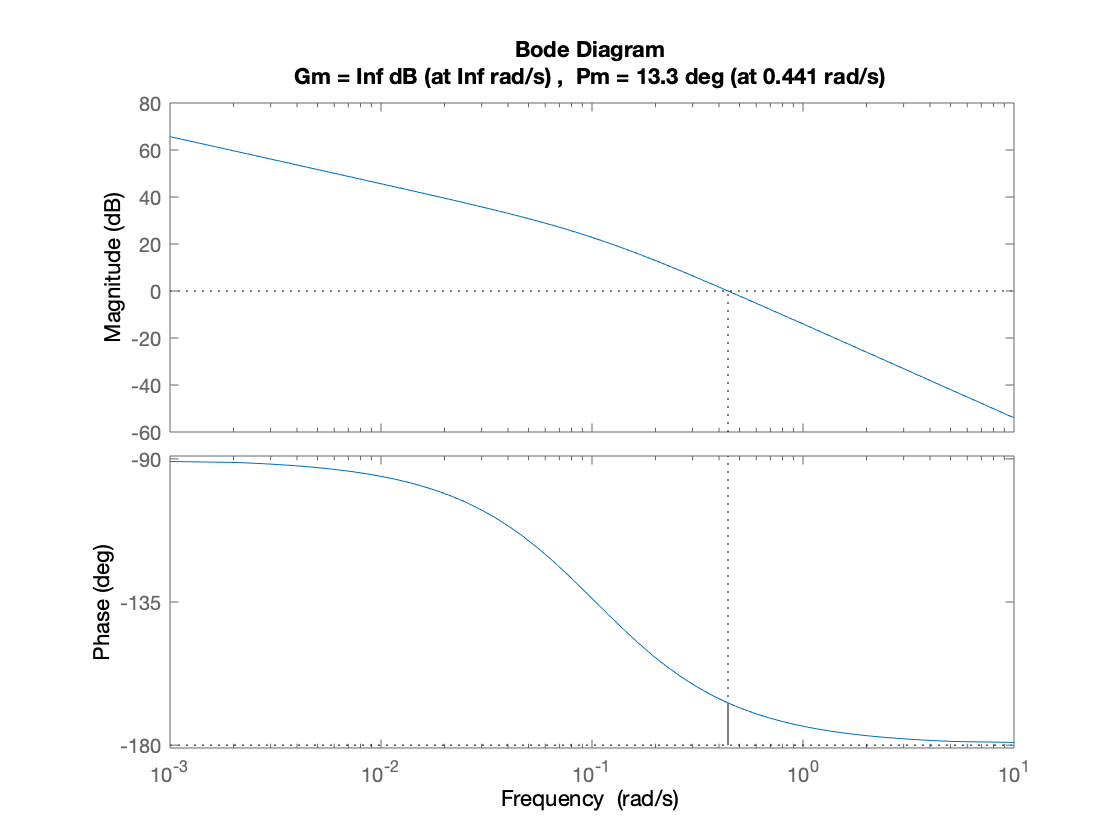

margin(G1)

*As seen by the margin plot, the gain margin is infinite and the phase margin is 13.3 degrees. *

3. Using a proportional gain (Kp), find the gain margin and phase margin of (Kpθ(s)/v(s)) for different Kp. Explain the connection between overshoot and phase margin using your observations. Explain how proportional gain is changing bode diagram and how it affects phase and gain margin.[10 marks] 												

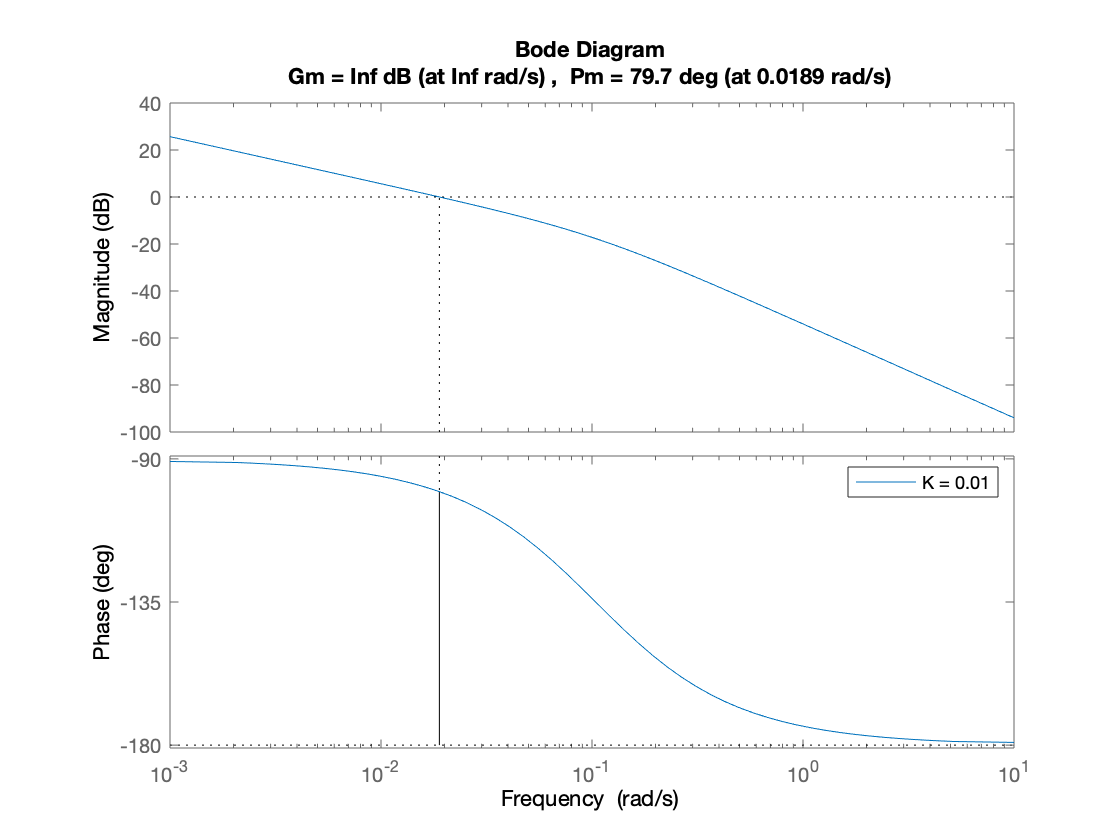

Kp = [0.01 0.1 1 10 100 1000];


margin(Kp(1,1)*G1)
legend('K = 0.01')

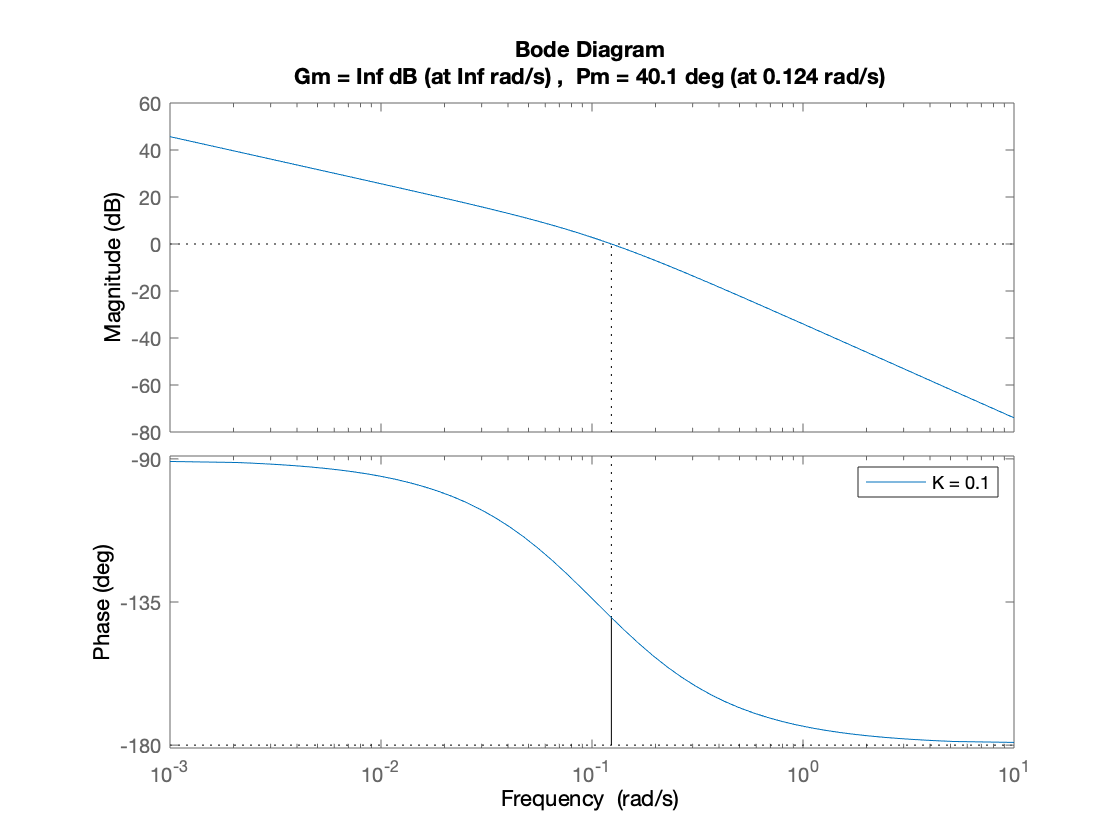


margin(Kp(1,2)*G1)
legend('K = 0.1')

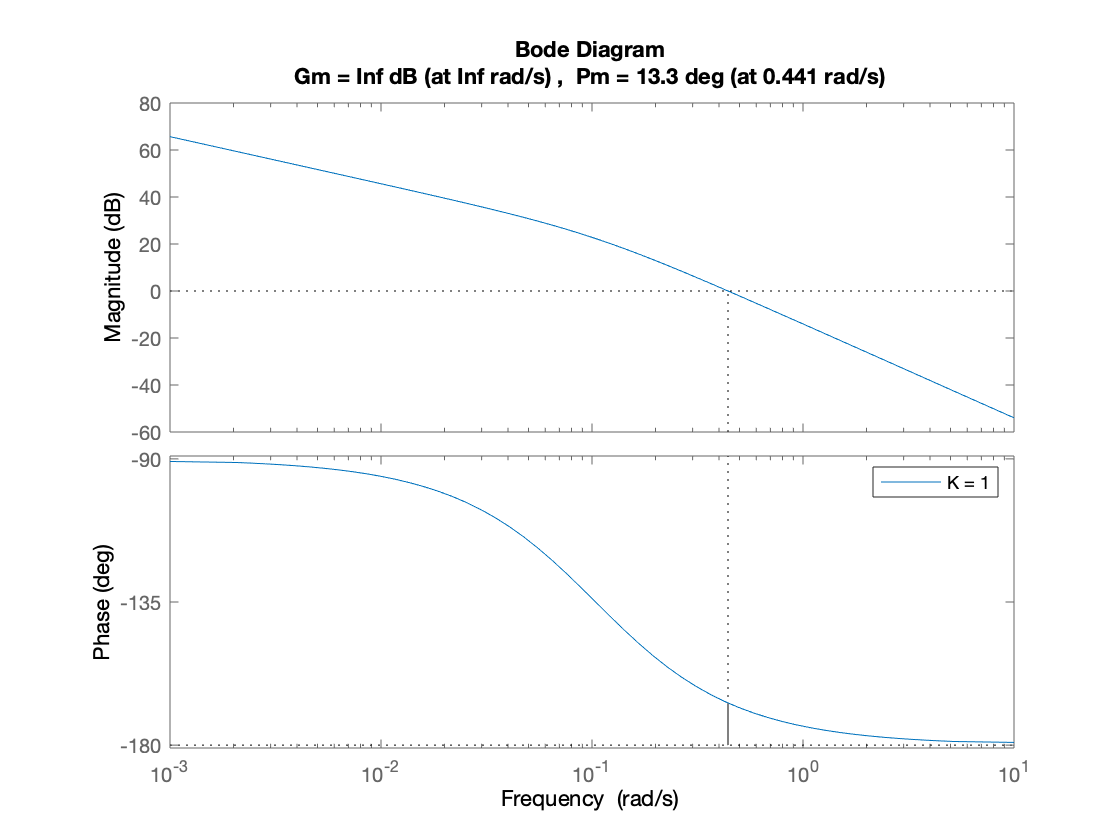


margin(Kp(1,3)*G1)
legend('K = 1')

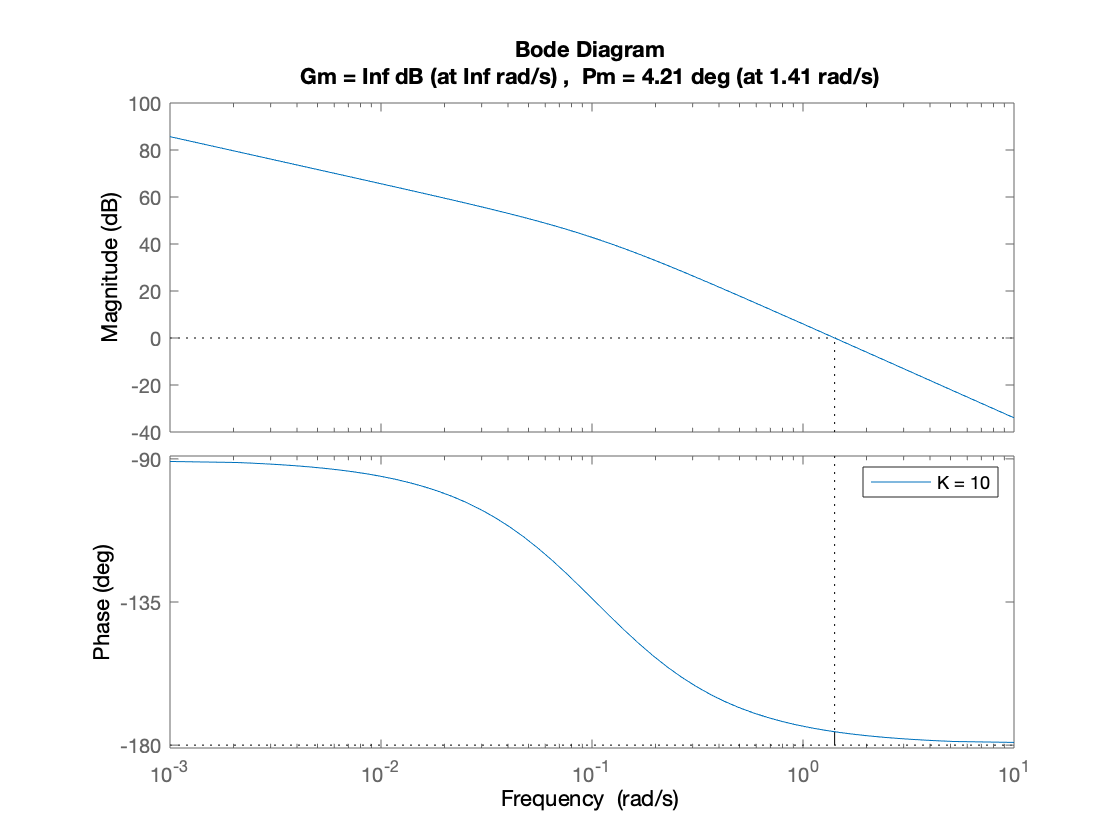


margin(Kp(1,4)*G1)
legend('K = 10')

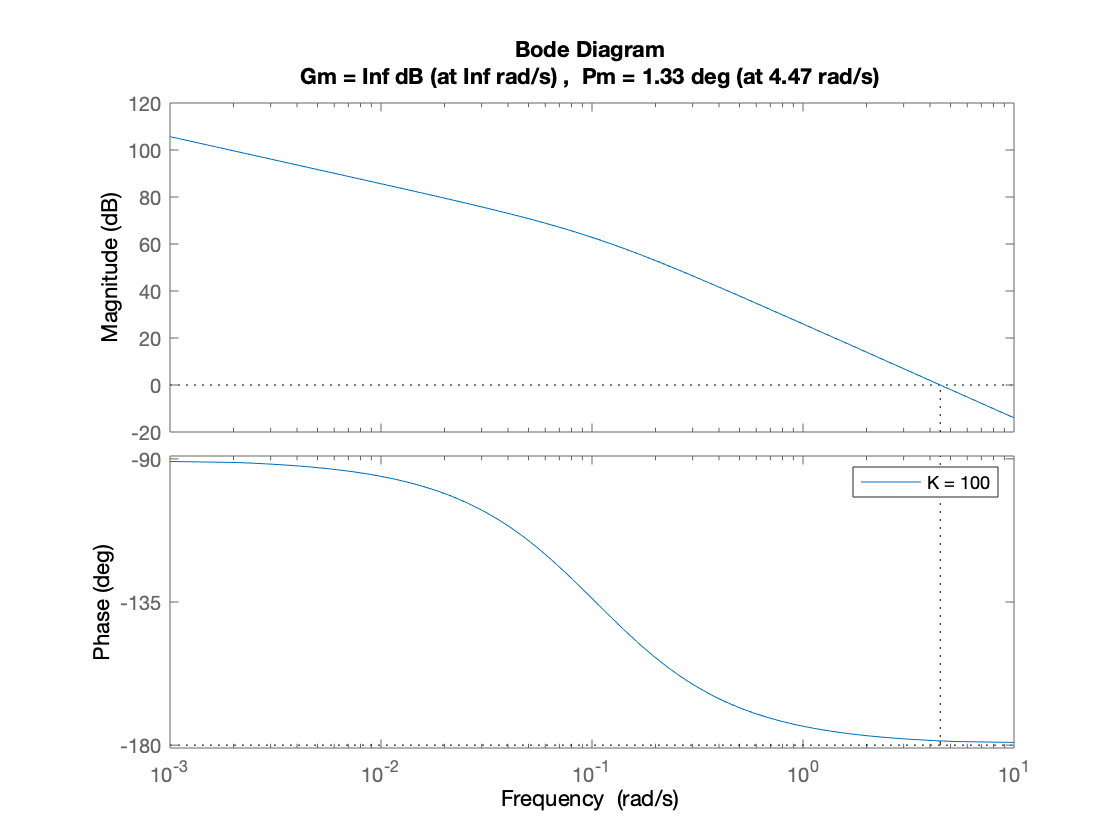


margin(Kp(1,5)*G1)
legend('K = 100')

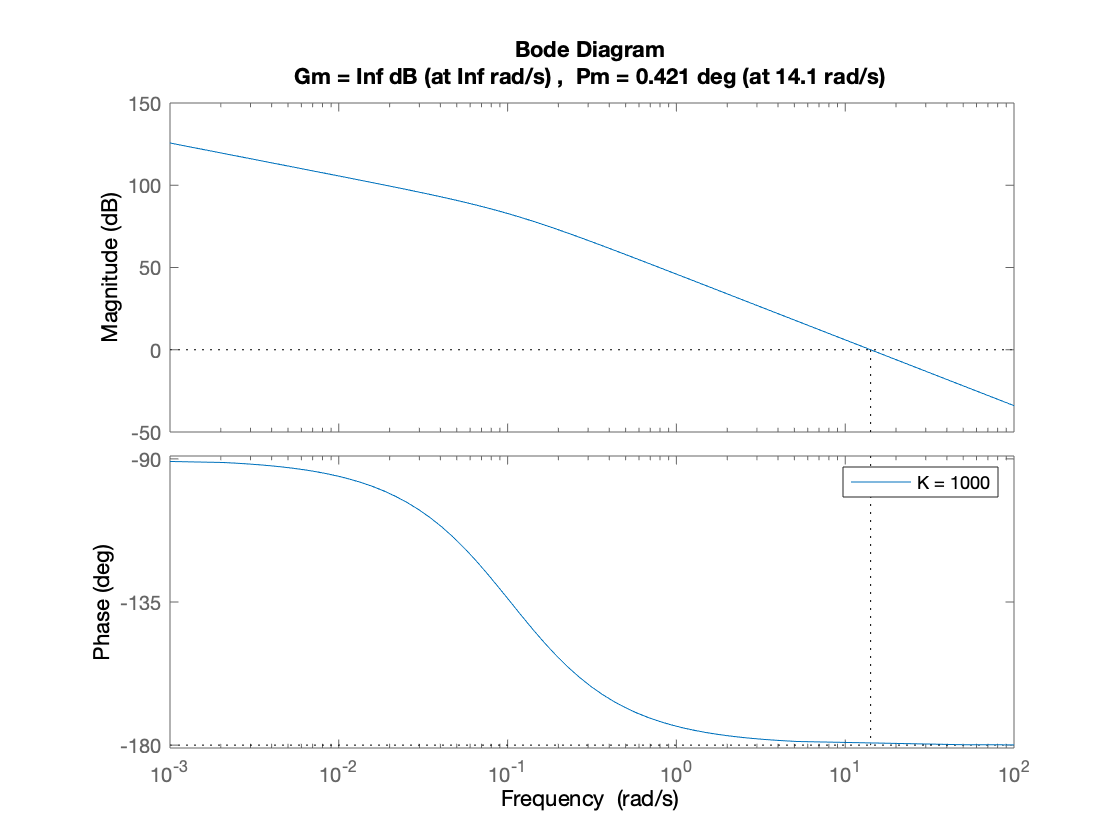


margin(Kp(1,6)*G1)
legend('K = 1000')

4. Consider unity feedback closed loop system with open loop plant θ(s)/v(s). Find the steady state error to step and ramp using final value theorem. Verify your answers by plotting the responses in MATLAB.[5 marks] 

s = tf('s')


s =
 
  s
 
Continuous-time transfer function.



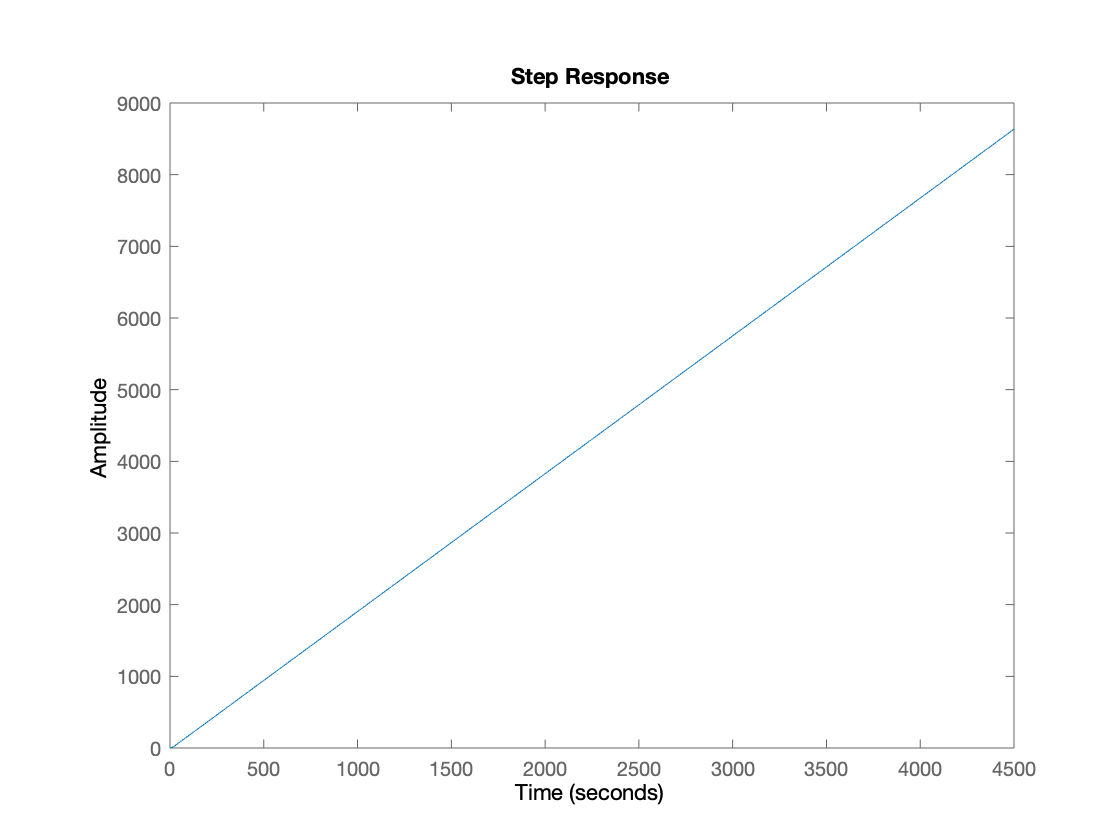

stepplot(G1)

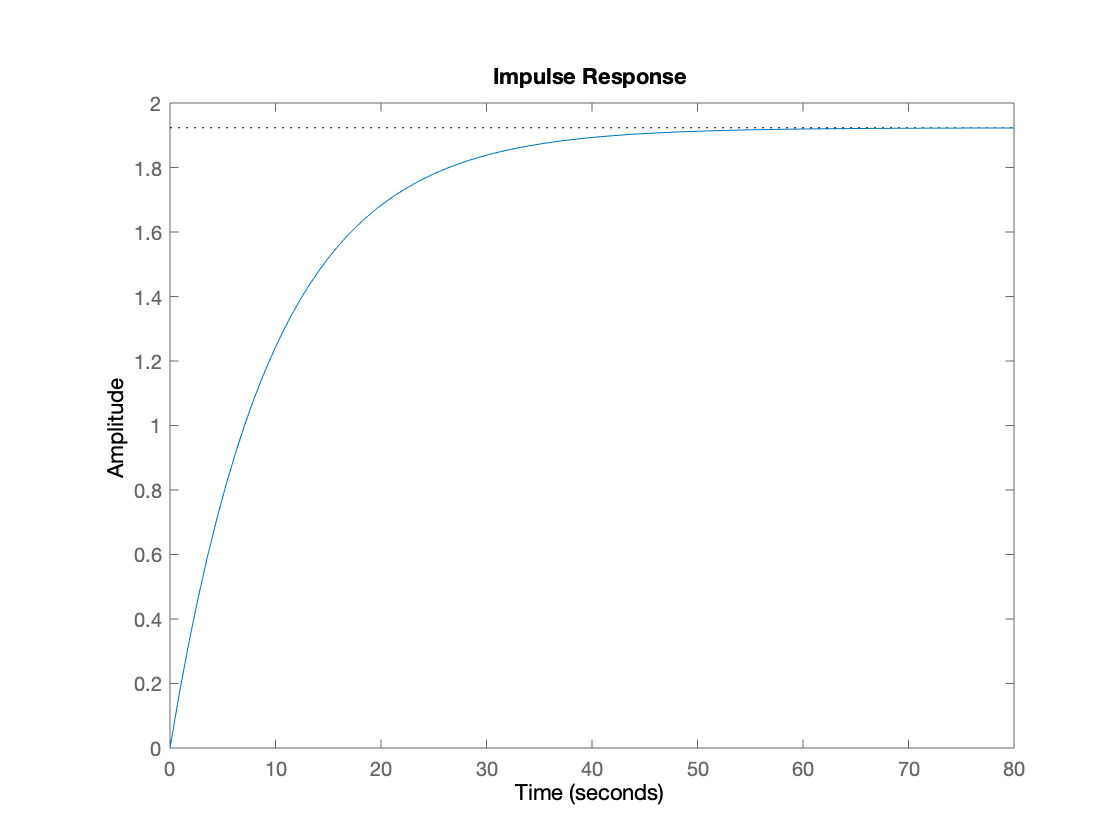


impulse(G1)


syms x
Va = 1/s;
G = 0.2 / (x^2 + 0.104*x)

$$G = \frac{1}{5\,\left(x^{2}+\frac{13\,x}{125}\right)}$$

Kv = double(limit(G*x, x, 0))

Kv = 1.9231


ss_ramp_error = 1/Kv

ss_ramp_error = 0.5200


%steady state ramp error is infinite


5. Design a lead controller which reduces the steady state error to a ramp signal to 0.1 and increases the phase margin of the system to 60. [20 marks] 

de = 0.1;
p_margin = 60;

K = (1/de)/Kv

K = 5.2000


[GM, PM] = margin(G1*K)

GM = Inf

PM = 5.8381

max_phase = 10 + p_margin - PM

max_phase = 64.1619

a = (1+sind(max_phase))/(1-sind(max_phase))

a = 19.0058


gain_wmax = -20*log10(sqrt(a))

gain_wmax = -12.7889

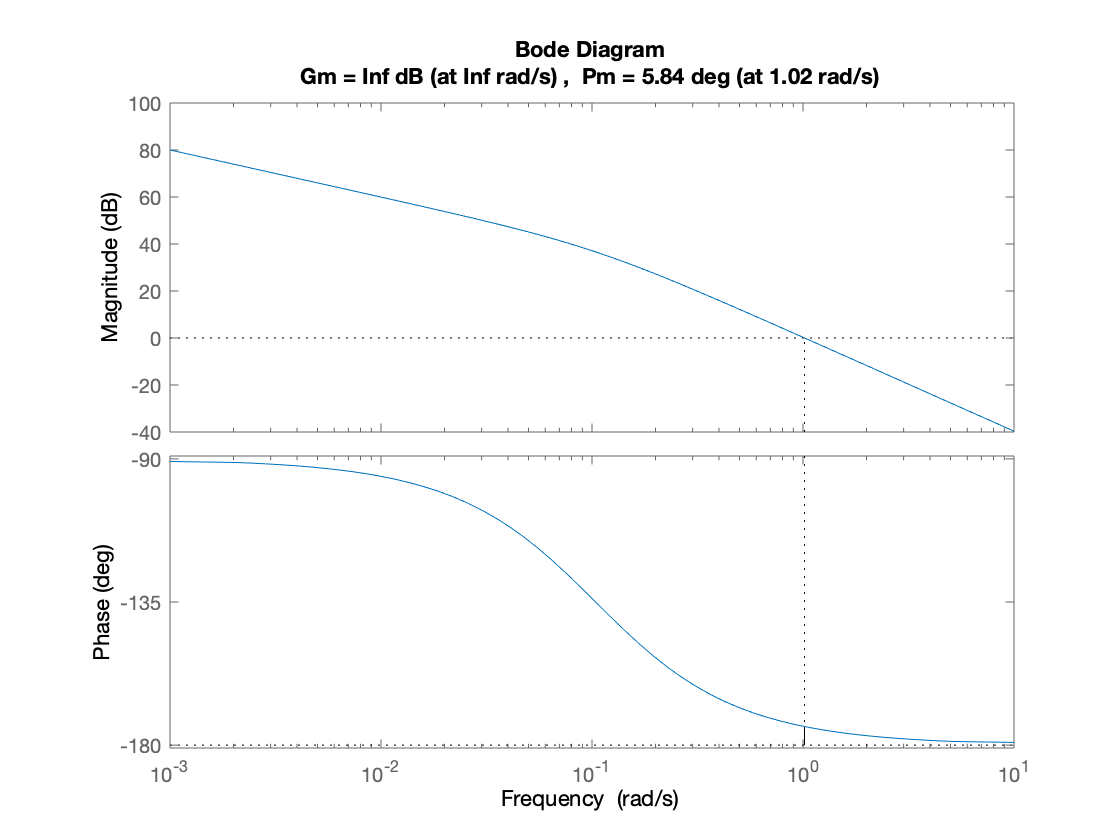

margin(G1*K)

*By inspection of the bode plot, w where Gain  = -12.78			*

wn = 2.11;
T = 1 / (wn * sqrt(a))

T = 0.1087


lead_contoller = K * (T*a*s + 1) / (T*s + 1)


lead_contoller =
 
  10.74 s + 5.2
  -------------
  0.1087 s + 1
 
Continuous-time transfer function.



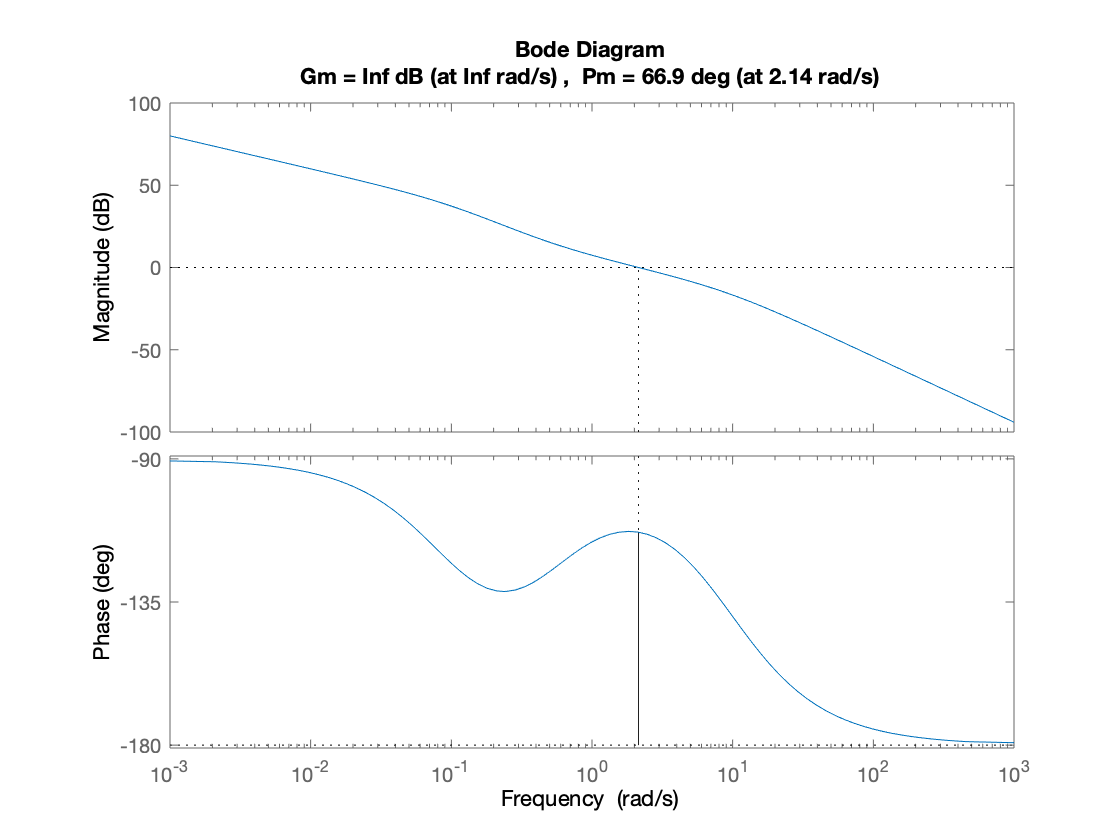

margin(G1*lead_contoller)

[GM2, PM2] = margin(G1*lead_contoller)

GM2 = Inf

PM2 = 66.9376

6. Is there a lead compensator which provides steady state error of 0 to ramp input? Justify your answer mathematically.[10 marks] 		

7. Plot the bode diagram of uncompensated, compensator and compensated systems in one diagram. Describe the relation between these diagrams. [5 marks] 	

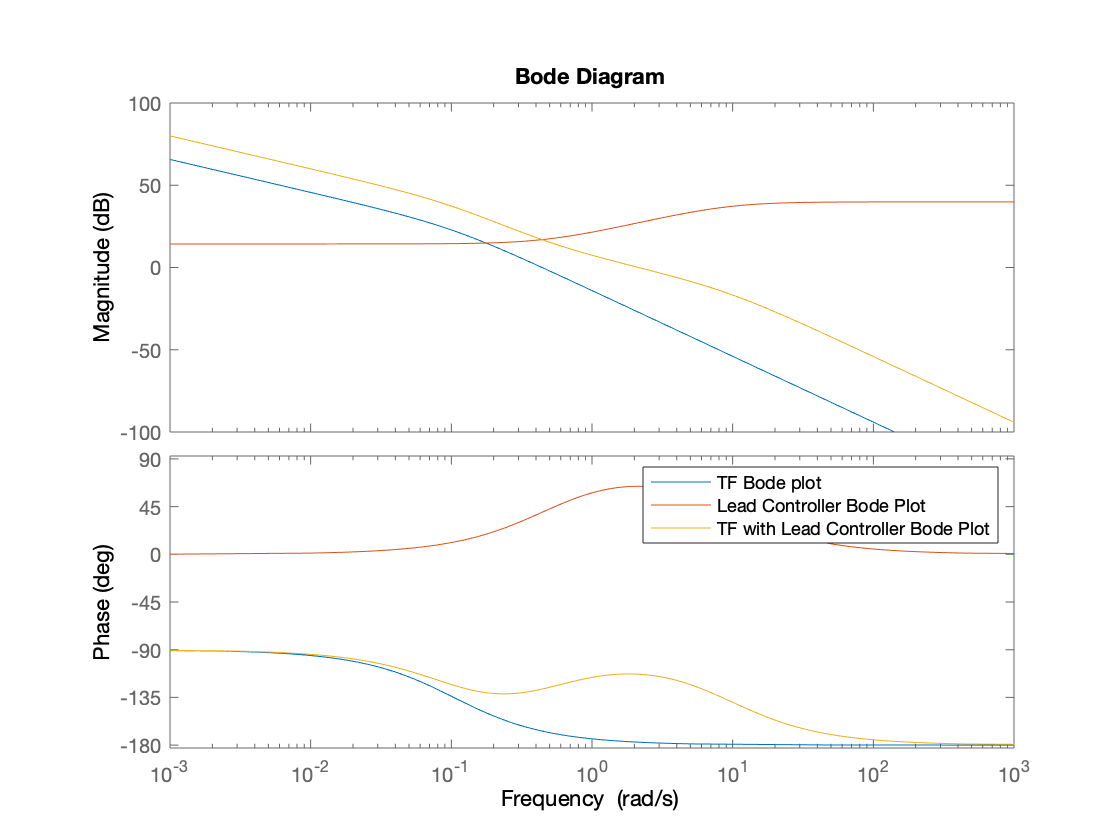

figure(1)
bode(G1)
hold on
bode(lead_contoller)
hold on
bode(G1*lead_contoller)
legend('TF Bode plot', 'Lead Controller Bode Plot', 'TF with Lead Controller Bode Plot')
hold off

8. Plot the ramp response of unity feedback closed loop system of compensated and uncompensated system, verify the steady state error is within the required region.[5 marks] 												

G2 = feedback(G1, 1)


G2 =
 
          0.2
  -------------------
  s^2 + 0.104 s + 0.2
 
Continuous-time transfer function.



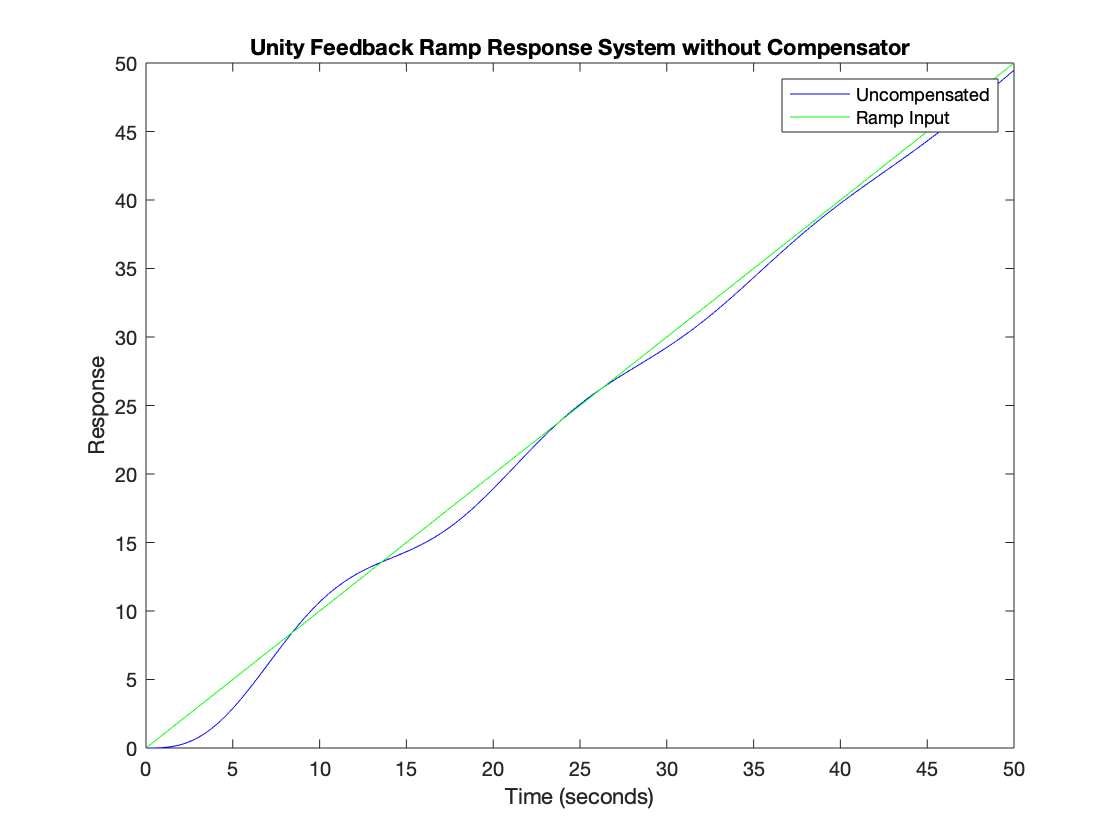


T = 0:0.01:50;
[y,t] = lsim(G2, T, T); 
plot(t,y,'b',t,T,'g')
xlabel('Time (seconds)') 
ylabel('Response')
 
title('Unity Feedback Ramp Response System without Compensator')
legend('Uncompensated', 'Ramp Input')

G3 = feedback(G1*lead_contoller, 1)


G3 =
 
                        
          2.149 s + 1.04
                        
  ------------------------------
                                
  0.1087 s^3 + 1.011 s^2        
                                
                + 2.253 s + 1.04
                                
 
Continuous-time transfer function.



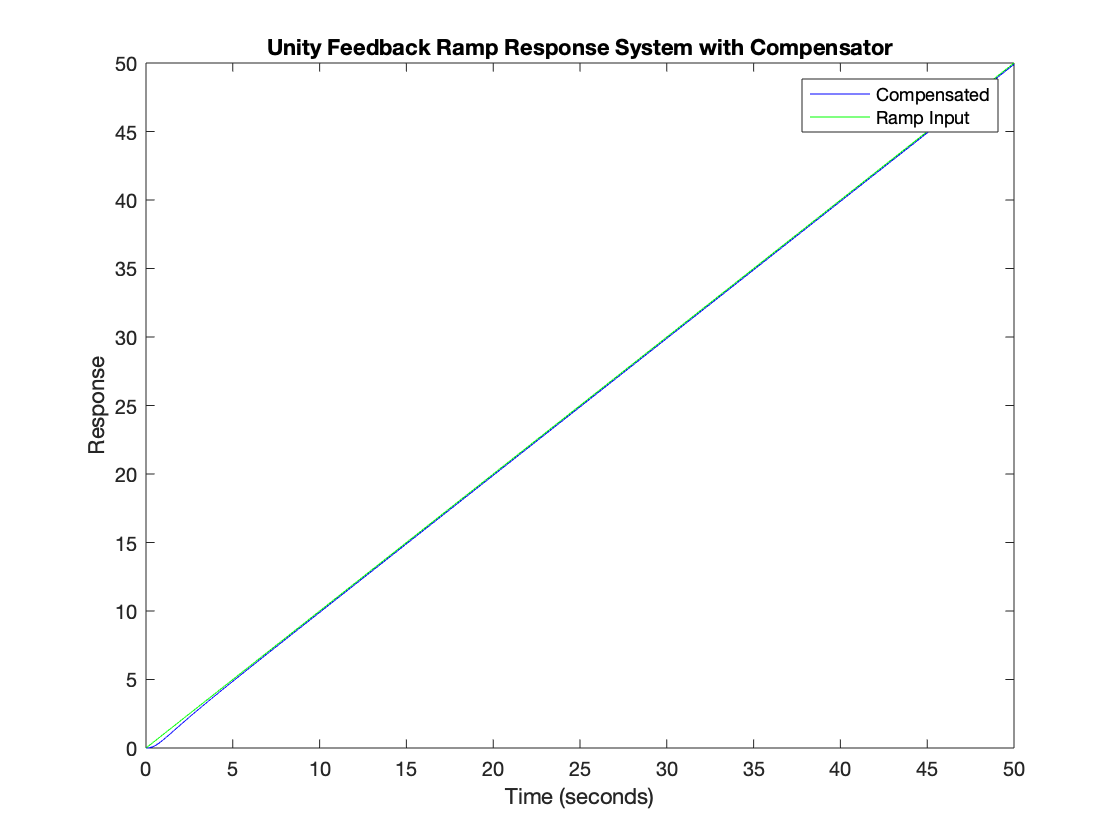

T = 0:0.01:50;
[y,t] = lsim(G3, T, T); 
plot(t,y,'b',t,T,'g')
xlabel('Time (seconds)') 
ylabel('Response')
 
title('Unity Feedback Ramp Response System with Compensator')
legend('Compensated', 'Ramp Input')

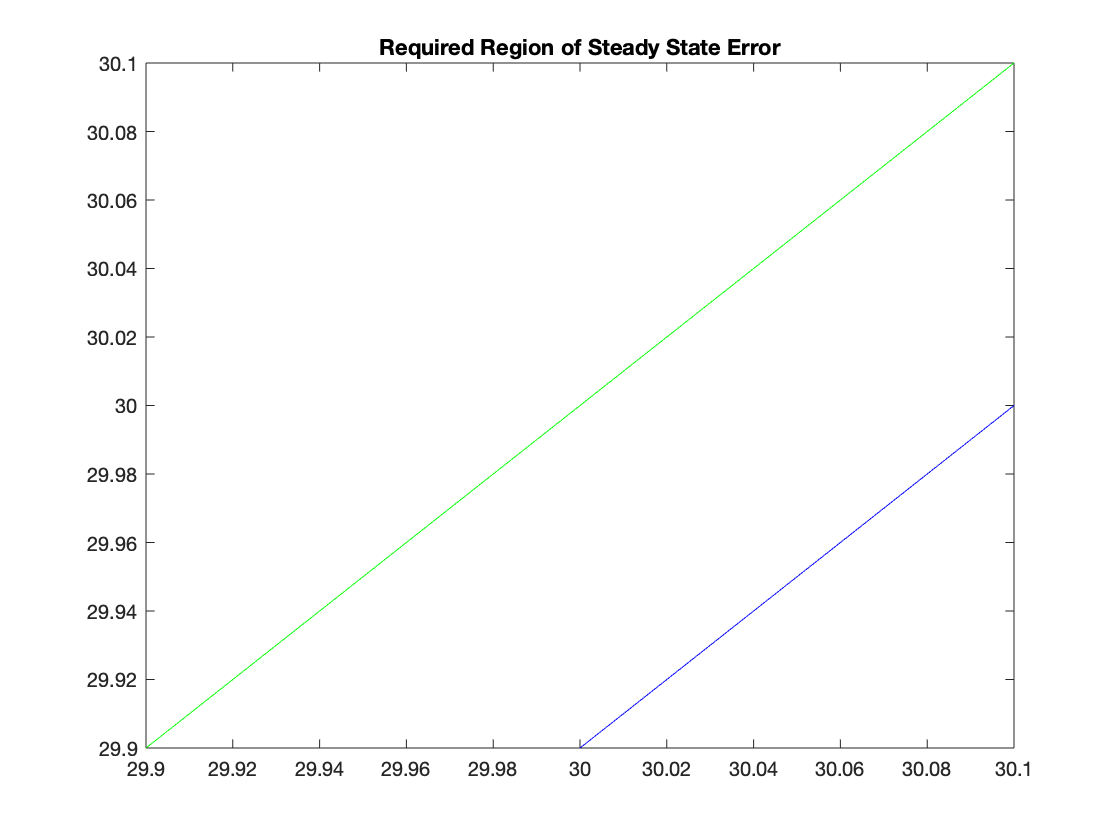

plot(t,y,'b',t,T,'g')
axis([29.9,30.1,29.9,30.1])
title('Required Region of Steady State Error')

9. Plot the root locus diagram of both compensated and uncompensated systems and describe the effect of a lead controller on poles of the system.[5 marks] 						

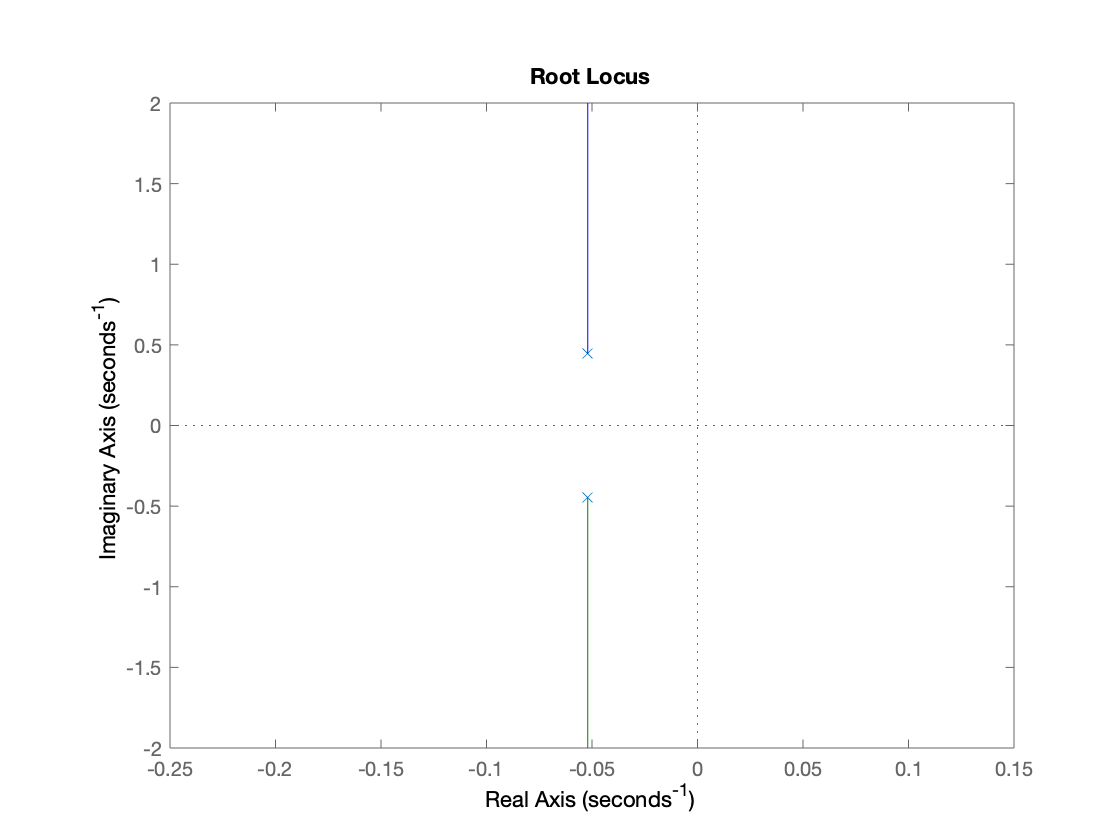

rlocus(G2)

[p1,z1] = pzmap(G2)

p1 =   -0.0520 + 0.4442i
  -0.0520 - 0.4442i



z1 =

  0×1 empty double column vector



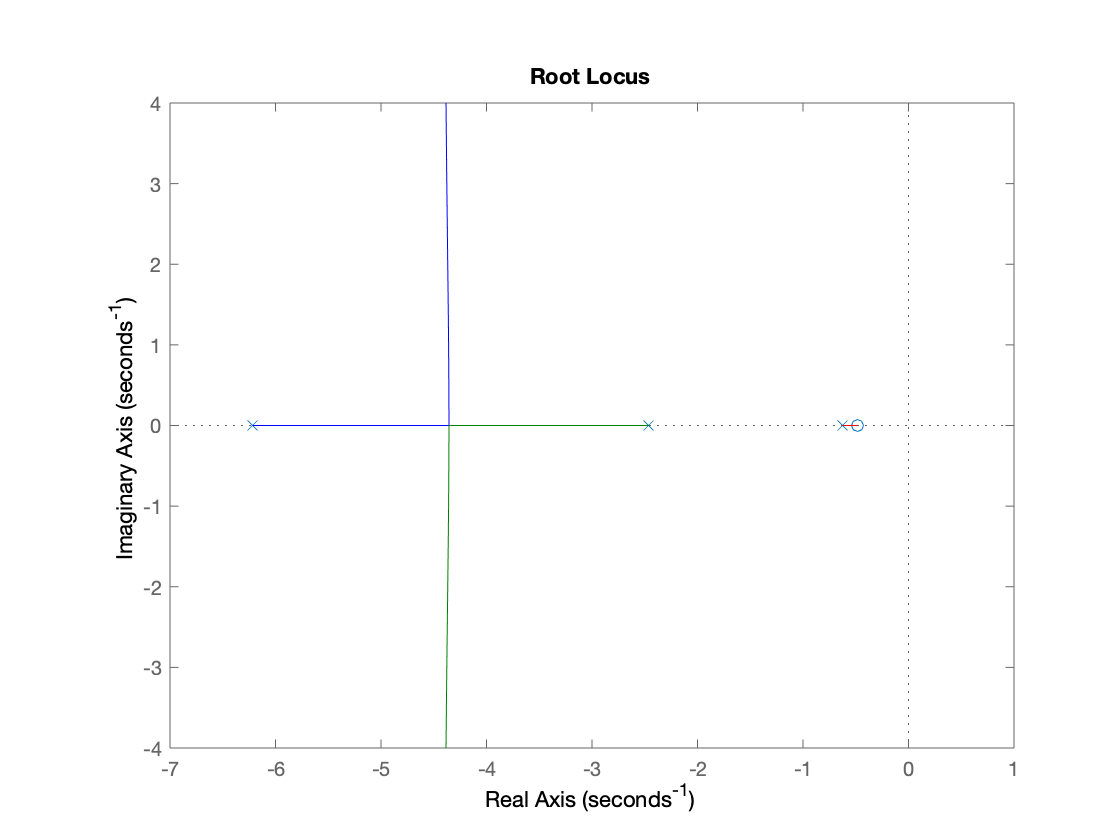


rlocus(G3)

[p2,z2] = pzmap(G3)

p2 =    -6.2169
   -2.4603
   -0.6255


z2 = -0.4840

10. Repeat steps of Question 5 for phase margins [50◦, 60◦, 70◦], and find corresponding compensator. Plotting step response of unity feedback closed loop compensated systems, describe the effect of different phase margins on the step responses.[15 marks] 

phase_margins = [50,60,70];

[GM, PM] = margin(G1*K);

max_phase = phase_margins(1,1) - PM + 10

max_phase = 54.1619

a = (1+sind(max_phase))/(1-sind(max_phase));
gain_wmax = -20*log10(sqrt(a))

gain_wmax = -9.8063

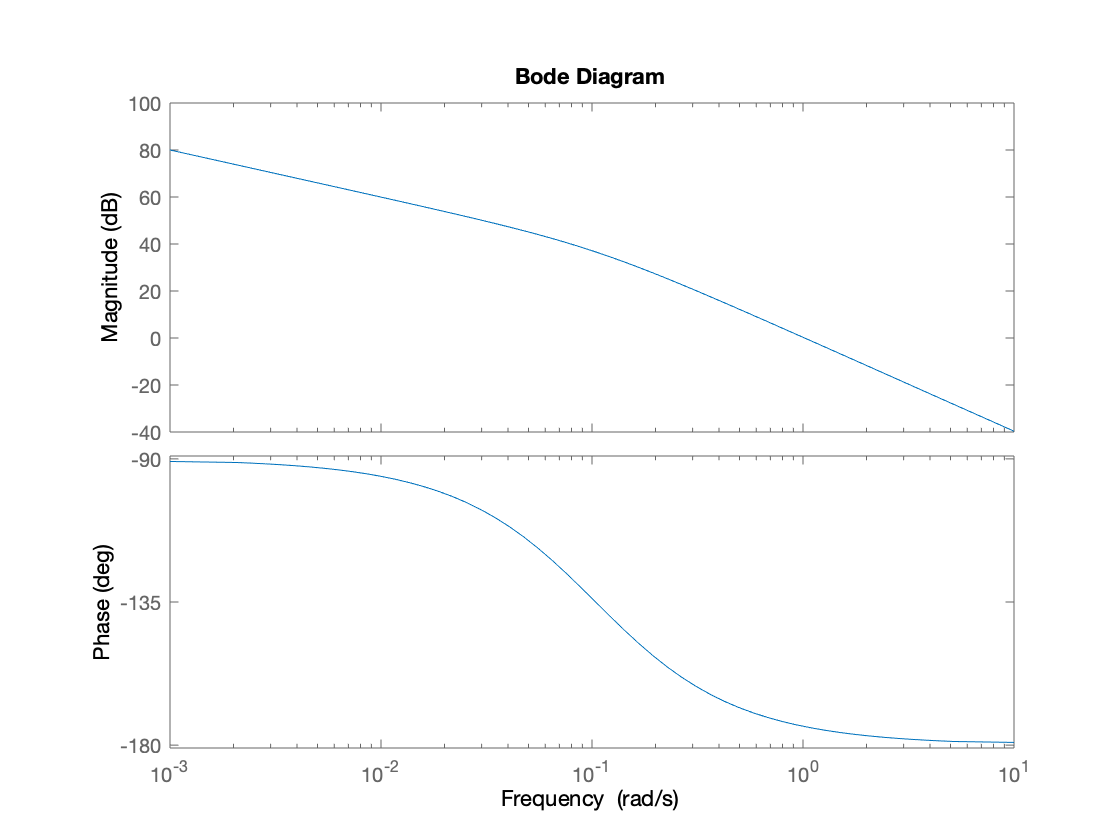

bode(G1*K)

%By inspection of Bode plot, we can get the natural frequency at which the gain is -9.8063
wn = 1.8;
t = 1/(wn * sqrt(a));
controller_3 = K * (a * t * s + 1)/(t * s + 1)


controller_3 =
 
  8.934 s + 5.2
  -------------
  0.1796 s + 1
 
Continuous-time transfer function.




[GM3, PM3] = margin(G1*controller_3)

GM3 = Inf

PM3 = 57.4930

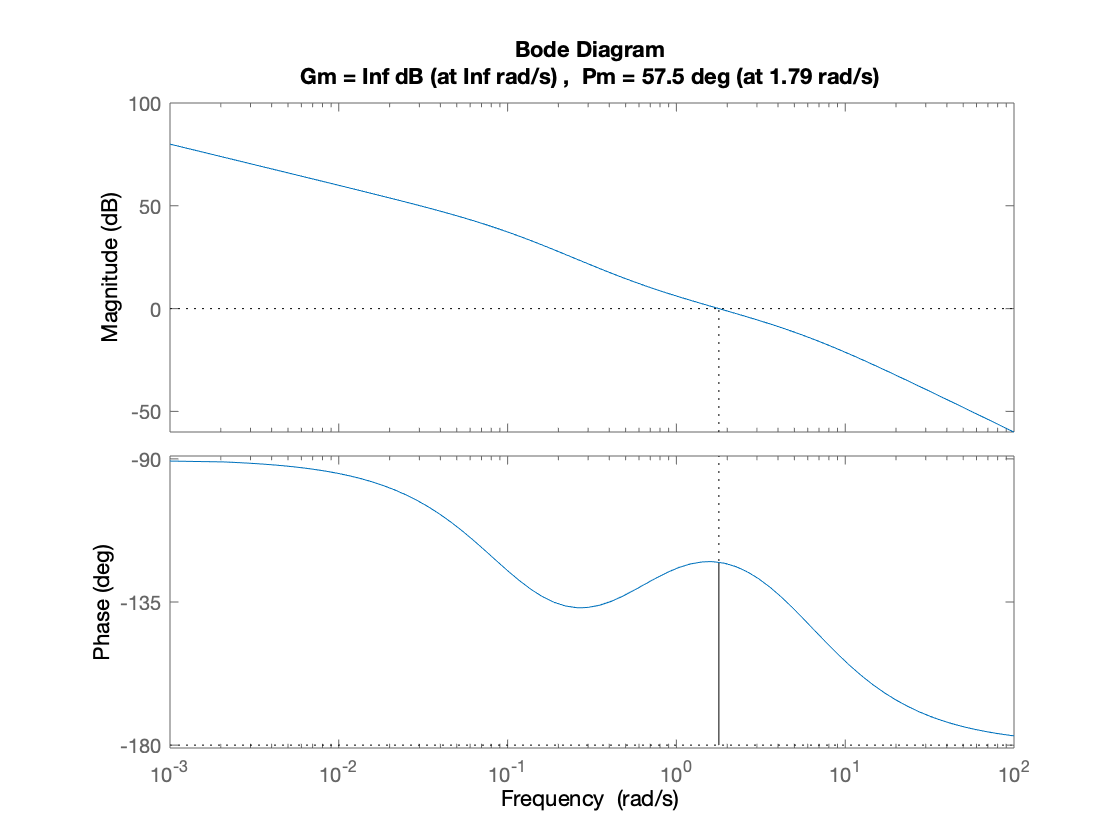

margin(G1*controller_3)

max_phase = phase_margins(1,2) - PM + 10

max_phase = 64.1619

a = (1+sind(max_phase))/(1-sind(max_phase)); 
gain_wmax = -20*log10(sqrt(a))

gain_wmax = -12.7889

bode(G1*K)

%By inspection of Bode plot, we can get the natural frequency at which the gain is -12.789
wn = 2.11;
t = 1/(wn * sqrt(a));
controller_4 = K * (a * t * s + 1)/(t * s + 1)


controller_4 =
 
  10.74 s + 5.2
  -------------
  0.1087 s + 1
 
Continuous-time transfer function.




[GM4, PM4] = margin(G1*controller_4)

GM4 = Inf

PM4 = 66.9376

margin(G1*controller_4)

max_phase = phase_margins(1,3) - PM + 10

max_phase = 74.1619

a = (1+sind(max_phase))/(1-sind(max_phase)); 
gain_wmax = -20*log10(sqrt(a))

gain_wmax = -17.1334

bode(G1*K)

%By inspection of Bode plot, we can get the natural frequency at which the gain is -17.1334
wn = 2.74;
t = 1/(wn * sqrt(a));
controller_5 = K * (a * t * s + 1)/(t * s + 1)


controller_5 =
 
  13.64 s + 5.2
  -------------
  0.05077 s + 1
 
Continuous-time transfer function.




[GM5, PM5] = margin(G1*controller_5)

GM5 = Inf

PM5 = 76.3456

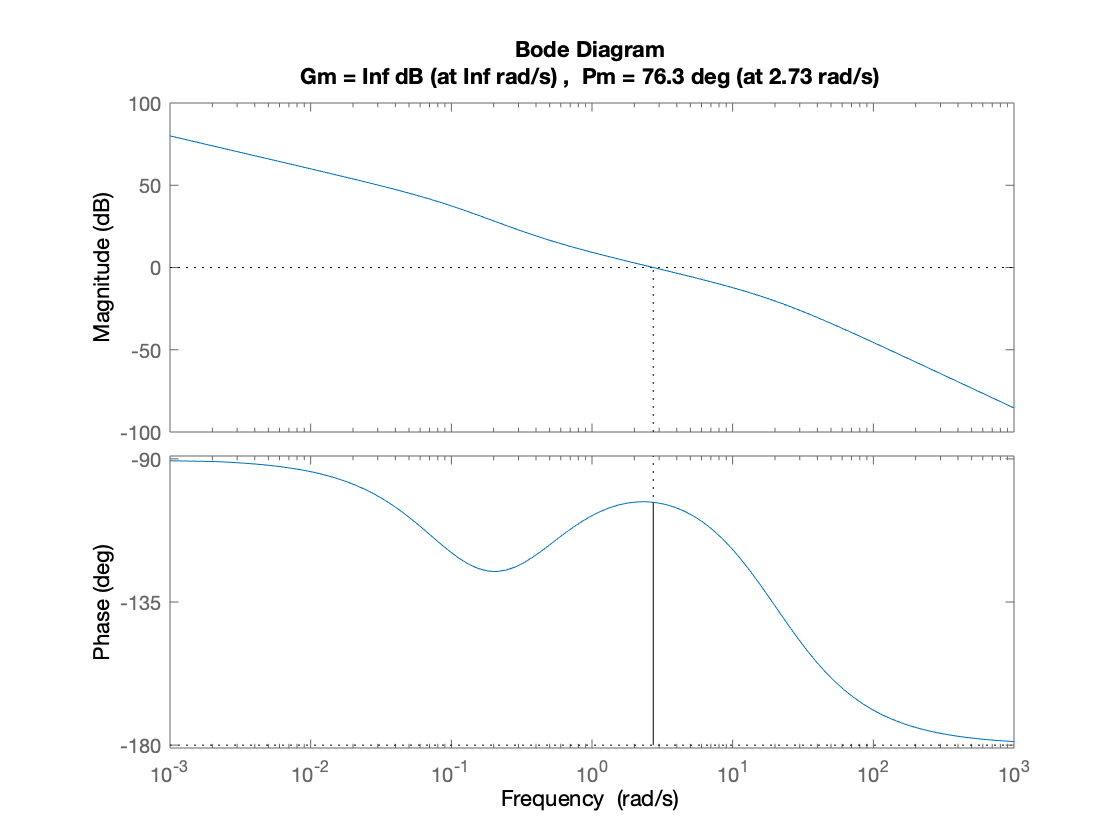

margin(G1*controller_5)



G3 = feedback(G1*controller_3, 1)


G3 =
 
                        
          1.787 s + 1.04
                        
  ------------------------------
                                
  0.1796 s^3 + 1.019 s^2        
                                
                + 1.891 s + 1.04
                                
 
Continuous-time transfer function.



G4 = feedback(G1*controller_4, 1)


G4 =
 
                        
          2.149 s + 1.04
                        
  ------------------------------
                                
  0.1087 s^3 + 1.011 s^2        
                                
                + 2.253 s + 1.04
                                
 
Continuous-time transfer function.



G5 = feedback(G1*controller_5, 1)


G5 =
 
                        
          2.729 s + 1.04
                        
  ------------------------------
                                
  0.05077 s^3 + 1.005 s^2       
                                
                + 2.833 s + 1.04
                                
 
Continuous-time transfer function.



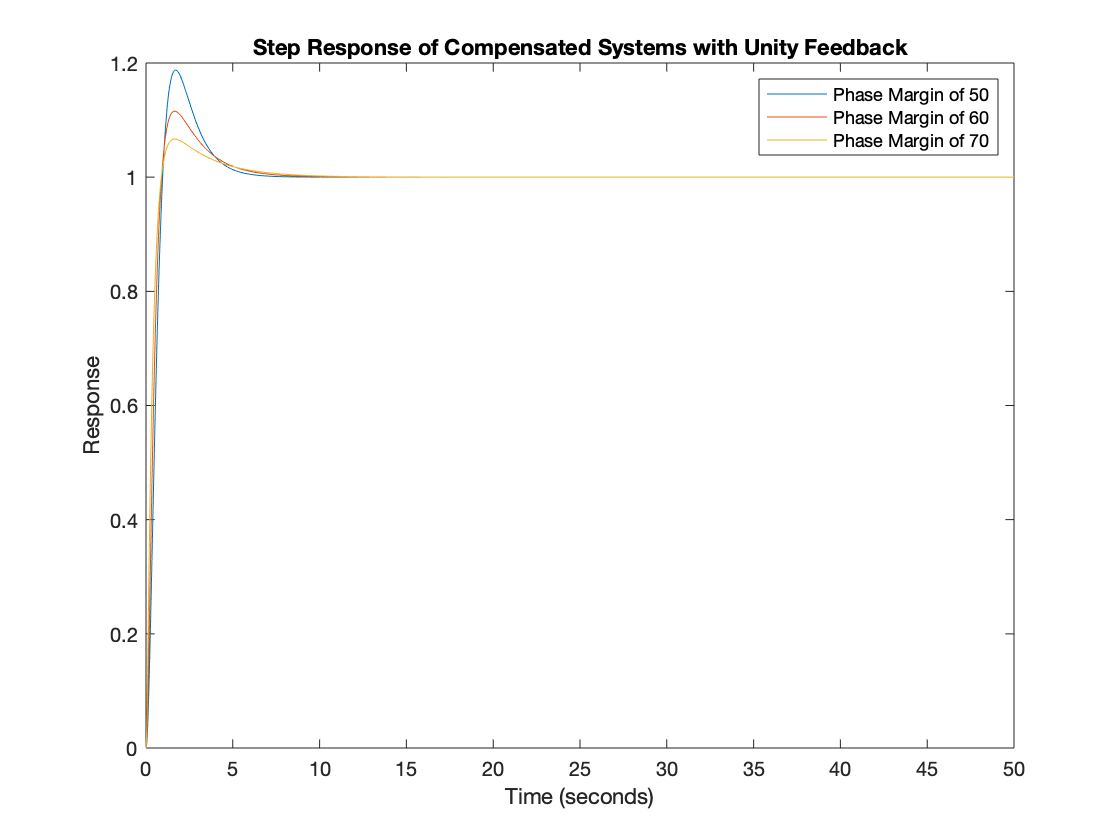


t = 0:0.01:50;
[y3,t3] = step(G3, t);
[y4,t4] = step(G4, t);
[y5,t5] = step(G5, t);

plot(t3, y3, t4, y4, t5, y5)
xlabel('Time (seconds)')
ylabel('Response')
title('Step Response of Compensated Systems with Unity Feedback')
legend('Phase Margin of 50','Phase Margin of 60','Phase Margin of 70')

11. Find crossover frequencies of compensated systems in Question 10. Explain the effect of crossover frequency on time domain response of the system. [10 marks] 				

[GM,PM,Wcg3,Wcp3] = margin(G1*controller_3);
Wcg3

Wcg3 = Inf

Wcp3

Wcp3 = 1.7864

[GM,PM,Wcg4,Wcp4] = margin(G1*controller_4);
Wcg4

Wcg4 = Inf

Wcp4

Wcp4 = 2.1429

[GM,PM,Wcg5,Wcp5] = margin(G1*controller_5);
Wcg5

Wcg5 = Inf

Wcp5

Wcp5 = 2.7272